**Progetto in ambito oncologico**

***Descrizione***:

Il progetto si propone di sviluppare un sistema integrato per la raccolta, archiviazione e analisi dei dati clinici relativi ai pazienti affetti da tumore al fegato. Questo sistema consente di gestire e valutare informazioni cruciali come diagnosi, trattamenti e esiti dei pazienti, e ha come obiettivi principali:

-  *Gestione dei dati*: fornire un metodo strutturato per inserire e aggiornare i dati dei pazienti, inclusi dettagli su diagnosi, tipo di tumore, trattamenti ricevuti e risultati dei follow-up.

- *Monitoraggio e analisi:* analizzare i dati raccolti per monitorare l'andamento della malattia e valutare l'efficacia dei trattamenti. Questo permette di identificare pattern e tendenze significative nel progresso della malattia e nella risposta ai trattamenti.

- *Supporto alla decisione clinica:* offrire strumenti per visualizzare e interpretare i dati attraverso grafici, aiutando i medici a prendere decisioni informate riguardo alle strategie terapeutiche e al follow-up dei pazienti.

- *Prevenzione e intervento: *Rilevare eventuali anomalie o deviazioni nei dati dei pazienti che possano richiedere un'attenzione medica tempestiva, migliorando la capacità di rispondere rapidamente a cambiamenti nella condizione dei pazienti.

***Creazione database***

Il database è già stato precedentemente creato su MySQL Workbench ed è il seguente: 

***Connessione al Database***

% Questo script gestisce l'interazione con il database per inserire e visualizzare pazienti.

% Specifica il nome del DSN, l'utente e la password
dsn = 'MySQL_LiverCancer';  
username = 'root';          
password = 'Miky2003@';     

% Crea una connessione al database
conn = database(dsn, username, password);

% Verifica se la connessione è riuscita
if isopen(conn)
    disp('Connessione al database riuscita.');
    randomInsertion(conn); % Chiama la funzione per l'inserimento dei dati
    menu(conn); % Questa sezione presenta un menu per interagire con il database
else
    disp('Connessione al database fallita.');
    disp(conn.Message);  % Mostra il messaggio di errore
    return;
end

***Progettazione Concettuale***

La progettazione concettuale si concentra sulla definizione delle entità principali del dominio di interesse e delle loro interrelazioni. 

Per il nostro progetto in ambito oncologico, sono state identificate due entità chiave:

- **Patients**: è un'entità che rappresenta le informazioni di base sui pazienti, tra i quali il codice identificativo, nome, cognome, età, genere e codice fiscale che risultano essere attributi.

- **Diagnoses**: è un'entità che rappresenta le informazioni sulle diagnosi associate ai pazienti e comprende i seguenti attributi, la data della diagnosi, il tipo di diagnosi e lo stadio del tumore e ovviamente il codice identificativo della diagnosi e del paziente.

- **Treatments**:  rappresenta l'entità che descrive i trattamenti somministrati ai pazienti. Ogni paziente, nel contesto del trattamento della patologia, può essere sottoposto a una specifica terapia o intervento medico al quale è collegato un esito, che deve essere registrato e tracciato nel sistema.

- **Outcomes**:  è un'entità che rappresenta lo stato clinico del paziente a seguito del trattamento per il tumore al fegato e durante i follow-up periodici. 

La relazione tra queste entità è a due a due di tipo uno-a-uno, ogni paziente ha una sola e unica diagnosi, un solo trattmento e un unico esito.

***Progettazione Logica***

Durante la fase di progettazione logica, il modello concettuale è stato trasformato in un modello logico adatto per l'implementazione su un database management system. In questa fase abbiamo definito le strutture delle tabelle e le chiavi:

**Tabella Patients**: Progettata per includere un identificativo unico per ogni paziente, oltre ai campi per nome, cognome, età, sesso e codice fiscale.

**Tabella Diagnoses**: comprende un identificativo unico per ogni diagnosi e per ogni paziente, quest'ultimo è una chiave esterna che fa riferimento alla chiave primaria contenuta nella tabella *Patients, *la data e il tipo di diagnosi.

**Tabella Treatments**: descrive le informazioni relative ai trattamenti ricevuti dai pazienti. Contiene vari attributi che sono stati definiti per memorizzare in modo dettagliato i dati relativi al trattamento del tumore al fegato. Anche in questo caso il paziente è identificato da una chiave esterna che fa riferimento alla chiave primaria contenuta nella tabella *Patients.*

**Tabella Outcomes**: contiene una serie di attributi che memorizzano informazioni dettagliate relative agli esiti della malattia o della terapia seguita dai pazienti. Così come nelle precedenti tabelle anche qui l'ID del paziente è una chiave esterna che fa riferimento alla chiave primaria contenuta nella tabella *Patients.*

***Progettazione Fisica***

Questa fase finale ha comportato l'implementazione fisica del database nel sistema di gestione scelto, MySQL Workbench. Le attività principali includono:

- **Creazione fisica delle tabelle**: Utilizzando comandi SQL per definire la struttura di ciascuna tabella secondo il modello logico.

- **Implementazione della CLI:** attraverso delle funzioni specifiche vi è la presenza di una Command-Line Interface che permette all'utente di aggiornare il database e ottenere informazioni.

**Diagramma ER**

ll diagramma Entità-Relazione (ER) riflette la struttura logica:

- **Patients** è l'entità principale che contiene informazioni sui pazienti..

- **Diagnoses**, **Treatments**, e **Outcomes** sono collegate alla tabella **Patients** tramite la chiave esterna **PatientID**.

- Le relazioni tra **Patients** e le altre tabelle sono di tipo "Uno a Uno", indicato dalla cardinalità "1:1". Questo significa che per ogni record in **Patients**, ci sarà esattamente un record associato nelle tabelle **Diagnoses**, **Treatments** e **Outcomes**.

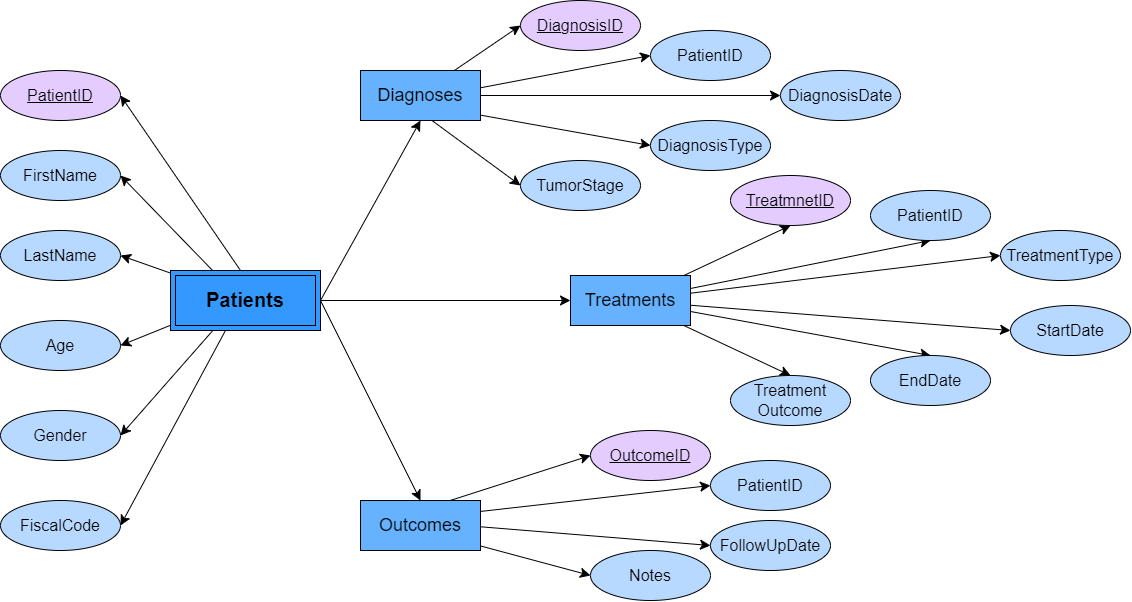

Funzione per gestire il menu

function menu(conn) 
    % Presenta un menu all'utente per scegliere l'operazione da eseguire
    while true
        fprintf("Seleziona un'opzione: \n\n"); 
        fprintf('1. Inserisci un paziente \n\n'); 
        fprintf('2. Visualizza informazioni su un paziente \n\n');
        fprintf('3. Visualizza grafici \n\n')
        fprintf('99. Esci \n\n'); 
        
        % Richiedi l'opzione all'utente
        option = input('Inserisci il numero dell''opzione scelta: ', 's'); 
        
        % Verifica l'opzione e esegui il codice corrispondente
        switch option
            case '1'
                % Inserisci paziente
                Add_Patient(conn);
                
            case '2'
                % Visualizza info paziente
                Info_patient(conn);
            case '3'
                % Visualizza grafici
                Graphs_Menu(conn);
                
            case '99'
                % Esci dal programma
                disp('Uscita dal programma.');
                break;
                
            otherwise
                % Opzione non valida
                disp('Opzione non valida. Per favore, seleziona un numero tra 1 e 99.');
        end
    end
    % Chiudi la connessione al database
    close(conn);
    disp('Connessione al database chiusa.');
end


`Inserimento dati`

function randomInsertion(conn)
    % Definisci i nomi e i cognomi per i pazienti
    firstNames = {'Luca', 'Giulia', 'Marco', 'Anna', 'Francesco', 'Laura', 'Alessandro', 'Sara', 'Matteo', 'Chiara'};
    lastNames = {'Rossi', 'Bianchi', 'Verdi', 'Russo', 'Ferrari', 'Esposito', 'Colombo', 'Romano', 'Ricci', 'Marino'};
    genderOptions = {'M', 'F'};

    % Array per tenere traccia dei codici fiscali già generati
    existingFiscalCodes = {};
    
    % Ciclo per generare e inserire i primi 50 pazienti
    for i = 1:50
        % Seleziona un nome e un cognome casualmente
        firstName = firstNames{randi(numel(firstNames))};
        lastName = lastNames{randi(numel(lastNames))};
        
        % Genera un'età casuale tra 18 e 90 anni
        age = randi([18, 90]);
        
        % Seleziona un genere casualmente
        gender = genderOptions{randi(2)};
        
        % Genera un codice fiscale unico
        fiscalCode = generateUniqueFiscalCode(existingFiscalCodes);
        
        % Aggiungi il codice fiscale all'array dei codici già esistenti
        existingFiscalCodes{end+1} = fiscalCode;
        
        % Crea la query SQL per inserire il paziente nel database
        sqlquery = sprintf("INSERT INTO Patients (PatientID, FirstName, LastName, Age, Gender, FiscalCode) VALUES (%d, '%s', '%s', %d, '%s', '%s')", i, firstName, lastName, age, gender, fiscalCode);

        % Esegui la query
        result = exec(conn, sqlquery);
        if ~isempty(result.Message)
            disp(['Errore nell''inserimento in Patients: ', result.Message]);
            return;
        end

        % Riempie automaticamente le tabelle Diagnoses, Treatments e Outcomes
        fillDiagnoses(conn, i);
        fillTreatments(conn, i);
        fillOutcomes(conn, i);

    end
end


Funzione per generare un codice fiscale unico

function code = generateUniqueFiscalCode(existingCodes)
    % Caratteri possibili per il codice fiscale
    characters = 'ABCDEFGHIJKLMNOPQRSTUVWXYZ0123456789';
    numChars = length(characters);
    
    % Variabile per verificare se il codice fiscale è unico
    isUnique = false;
    
    % Continua a generare un codice fiscale finché non è unico
    while ~isUnique
        % Genera un codice fiscale casuale di 16 caratteri
        code = characters(randi(numChars, 1, 16));
        
        % Verifica se il codice fiscale è unico
        if ~ismember(code, existingCodes)
            isUnique = true;
        end
    end
end


Funzione per generare menu dei grafici

function Graphs_Menu(conn)
    while true
        fprintf('Seleziona il tipo di grafico da generare: \n\n');
        fprintf('1. Distribuzione delle età \n\n');
        fprintf('2. Distrubuzione tipo di cancro \n\n');
        fprintf('3. Distribuzione esiti \n\n');
        fprintf('99. Torna al menu principale \n\n');

        graficoOption = input('Inserisci il numero del grafico scelto: ', 's');

        switch graficoOption
            case '1'
                AgeGraph(conn);  % Genera istogramma età
            case '2'
                TumorGraph(conn);  % Genera grafico a barre per genere
            case '3'
                OutcomesGraph(conn); % Genera grafico a torta per esiti
            case '99'
                break;  % Torna al menu principale
            otherwise
                disp('Opzione non valida. Per favore seleziona un numero corretto.');
        end
    end
end

Funzione per aggiungere un paziente

function Add_Patient(conn)
    % Richiedi l'input dell'utente
    patient_ID = str2double(input('Inserire ID: ', 's'));  % Converte l'ID in numero
    patientFirstName = input('Inserire nome: ', 's');
    patientLastName = input('Inserire cognome: ', 's');
    patientAge = str2double(input('Inserire età: ', 's'));  % Converte l'età in numero
    patientGender = input('Inserire genere (M/F): ', 's');
    patientFiscalCode = input('Inserire codice fiscale: ', 's');
    
    % Verifica che l'ID e l'età siano numeri validi
    if isnan(patient_ID) || isnan(patientAge)
        disp('Errore: ID e età devono essere numeri validi.');
        return;
    end

    % Creazione della query SQL
    sqlquery6 = sprintf("INSERT INTO Patients (PatientID, FirstName, LastName, Age, Gender, FiscalCode) VALUES (%d, '%s', '%s', %d, '%s', '%s')", ...
        patient_ID, patientFirstName, patientLastName, patientAge, patientGender, patientFiscalCode);
    
    % Esegui la query
    result = exec(conn, sqlquery6);
    
    % Controlla se la query ha avuto successo
    if ~isempty(result.Message)
        disp(['Errore nell''inserimento in Patients: ID già presente']);
    else
        disp('Paziente inserito con successo.');
        % Esegui le altre query per Diagnoses, Treatments e Outcomes
        fillDiagnoses(conn, patient_ID);
        fillTreatments(conn, patient_ID);
        fillOutcomes(conn, patient_ID);
    end
end

Funzione per inserire dati nella tabella Diagnoses

function fillDiagnoses(conn, patient_ID)
    diagnosisTypes = {'Carcinoma', 'Linfoma', 'Sarcoma', 'Melanoma'};
    tumorStages = {'I', 'II', 'III', 'IV'};
    
    diagnosisDate = datestr(datetime('today') - randi([1 365]), 'yyyy-mm-dd');
    diagnosisType = diagnosisTypes{randi(numel(diagnosisTypes))};
    tumorStage = tumorStages{randi(numel(tumorStages))};
    
    sqlquery = sprintf("INSERT INTO Diagnoses (D_PatientID, DiagnosisDate, DiagnosisType, TumorStage) VALUES (%d, '%s', '%s', '%s')", patient_ID, diagnosisDate, diagnosisType, tumorStage);  
    exec(conn, sqlquery);
    %disp('Dati inseriti nella tabella Diagnoses');
end


Funzione per inserire dati nella tabella Treatments

function fillTreatments(conn, patient_ID)
    treatmentTypes = {'Chemioterapia', 'Radioterapia', 'Chirurgia', 'Immunoterapia'};
    treatmentOutcomes = {'In corso', 'Completato', 'Fallito', 'Sospeso'};
    
    startDate = datestr(datetime('today') - randi([30 180]), 'yyyy-mm-dd');
    endDate = datestr(datetime('today') - randi([1 29]), 'yyyy-mm-dd');
    
    % Seleziona Chirurgia per stadi I o II come esempio fittizio
    if rand > 0.5
        treatmentType = 'Chirurgia';
    else
        treatmentType = treatmentTypes{randi(length(treatmentTypes))};
    end
    
    treatmentOutcome = treatmentOutcomes{randi(length(treatmentOutcomes))};
    
    sqlquery = sprintf("INSERT INTO Treatments (T_PatientID, TreatmentType, StartDate, EndDate, TreatmentOutcome) VALUES (%d, '%s', '%s', '%s', '%s')", patient_ID, treatmentType, startDate, endDate, treatmentOutcome);
    exec(conn, sqlquery);
    
    %disp('Dati inseriti nella tabella Treatments');
end


Funzione per inserire dati nella tabella Outcomes

function fillOutcomes(conn, patient_ID)
    statusTypes = {'Stabile', 'Progredito', 'Remissione', 'Deceduto'};
    
    followUpDate = datestr(datetime('today') - randi([1 180]), 'yyyy-mm-dd');
    status = statusTypes{randi(length(statusTypes))};
    notes = 'Follow-up periodico';
    
    sqlquery = sprintf("INSERT INTO Outcomes (O_PatientID, FollowUpDate, Status, Notes) VALUES (%d, '%s', '%s', '%s')", patient_ID, followUpDate, status, notes);
    try
        exec(conn, sqlquery);
    catch exception
        disp('Errore durante l''inserimento:');
        disp(exception.message);
    end

    
    %disp('Dati inseriti nella tabella Outcomes');
end

Funzione per visualizzare informazioni sui pazienti

function Info_patient(conn)
    patient_ID = input('Inserire PatientID: ', 's');  % Assicurati che l'ID venga letto come stringa
    query_patients = sprintf('SELECT * FROM Patients WHERE PatientID = ''%s''', patient_ID);
    query_diagnoses = sprintf('SELECT * FROM Diagnoses WHERE D_PatientID = ''%s''', patient_ID);
    query_treatments = sprintf('SELECT * FROM Treatments WHERE T_PatientID = ''%s''', patient_ID);
    query_outcomes = sprintf('SELECT * FROM Outcomes WHERE O_PatientID = ''%s''', patient_ID);
    
    % Estrazione dei dati dai vari campi
    data_patients = fetch(conn, query_patients);
    data_diagnoses = fetch(conn, query_diagnoses);
    data_treatments = fetch(conn, query_treatments);
    data_outcomes = fetch(conn, query_outcomes);
    
    % Verifica se i dati del paziente esistono
    if isempty(data_patients)
        disp('Nessun paziente trovato per l''ID inserito.');
        return; % Se nessun paziente viene trovato, esce dalla funzione
    else
        % Se il paziente esiste, stampa le informazioni
        patient_info = sprintf('Nome: %s, Cognome: %s, Età: %d, Genere: %s, Codice fiscale: %s', ...
            data_patients.FirstName{1}, data_patients.LastName{1}, data_patients.Age(1), data_patients.Gender{1}, data_patients.FiscalCode{1});
        disp(patient_info);
        disp(' ');
    end
    
    % Verifica e stampa diagnosi se esistono
    if isempty(data_diagnoses)
        disp('Nessuna diagnosi trovata per il paziente.');
    else
        diagnose_info = sprintf('Data e tipo di diagnosi: %s, %s, Stadio: %s', ...
            data_diagnoses.DiagnosisDate{1}, data_diagnoses.DiagnosisType{1}, data_diagnoses.TumorStage{1});
        disp(diagnose_info);
        disp(' ');
    end
    
    % Verifica e stampa trattamenti se esistono
    if isempty(data_treatments)
        disp('Nessun trattamento trovato per il paziente.');
    else
        treatment_info = sprintf('Tipo di trattamento: %s, Periodo del trattamento: %s - %s, Esito: %s', ...
            data_treatments.TreatmentType{1}, data_treatments.StartDate{1}, data_treatments.EndDate{1}, data_treatments.TreatmentOutcome{1});
        disp(treatment_info);
        disp(' ');
    end
    
    % Verifica e stampa esiti se esistono
    if isempty(data_outcomes)
        disp('Nessun follow-up trovato per il paziente.');
    else
        outcome_info = sprintf('Data follow-up: %s, Stato: %s, Note: %s', ...
            data_outcomes.FollowUpDate{1}, data_outcomes.Status{1}, data_outcomes.Notes{1});
        disp(outcome_info);
        disp(' ');
    end
end

Funzione grafico età

function AgeGraph(conn)
    % Query per ottenere i dati dell'età dei pazienti
    query = 'SELECT Age FROM Patients';
    data = fetch(conn, query);

    % Controllo dati
    if isempty(data)
        disp('Nessun dato recuperato.');
        return;
    end

    % Converte in array se necessario
    eta = data.Age;

    % Conta il numero di pazienti per ciascuna età
    uniqueAges = unique(eta);
    patientCount = histc(eta, uniqueAges);

    % Crea il grafico a barre orizzontali
    figure;
    b = barh(uniqueAges, patientCount, 'FaceColor', 'flat');  % Crea il grafico a barre orizzontali

    % Definisci una matrice di colori alternati (es. blu e rosso)
    colors = [0 0.5 1; 1 0 0];  % Blu e rosso

    % Alterna i colori tra le barre
    for i = 1:length(uniqueAges)
        b.CData(i, :) = colors(mod(i-1, 2) + 1, :);  % Alterna tra blu e rosso
    end

    % Aggiungi titolo e etichette
    title('Distribuzione delle età dei pazienti');
    xlabel('Numero di pazienti');
    ylabel('Età');
    grid on;
end

Funzione per creare un grafico sulla distribuzione dei diversi tipi di tumore

function TumorGraph(conn)
    % Query per estrarre i tipi di diagnosi
    query = 'SELECT DiagnosisType FROM Diagnoses';

    % Esecuzione della query
    data = fetch(conn, query);

    % Controlla se ci sono risultati
    if isempty(data)
        disp('Nessun dato trovato nella tabella Diagnoses.');
        return;
    end

    % Estrai i tipi di diagnosi dalla tabella
    diagnosisTypes = data.DiagnosisType;

    % Verifica il tipo dei dati
    disp('Tipo di dati estratti:');
    disp(class(diagnosisTypes));

    % Conta il numero di diagnosi per ciascun tipo
    if iscell(diagnosisTypes)
        diagnosisCategories = categorical(diagnosisTypes);
    else
        disp('I dati non sono in formato cella, quindi potrebbe essere necessario convertirli.');
        diagnosisCategories = categorical(cellstr(num2str(diagnosisTypes)));
    end

    % Conta il numero di diagnosi per ciascun tipo
    [typeCounts, typeLabels] = histcounts(diagnosisCategories, 'Categories', categories(diagnosisCategories));

    % Crea il grafico a barre
    figure;
    hBar = bar(typeCounts);

    % Definisci una mappa di colori
    numBars = length(typeCounts);
    colors = lines(numBars); % Usa la mappa di colori predefinita "lines" per generare colori
    % colors = [1 0 0; 0 1 0; 0 0 1; 1 1 0; ... ]; % Definisci manualmente se preferisci

    % Assegna i colori alle barre
    for i = 1:numBars
        hBar.FaceColor = 'flat';
        hBar.CData(i, :) = colors(i, :);
    end

    set(gca, 'XTickLabel', typeLabels);
    xlabel('Tipo di Cancro al Fegato');
    ylabel('Numero di Diagnosi');
    title('Distribuzione dei Tipi di Cancro al Fegato');
    grid on;
end

Funzione per creare un grafico sulla distribuzione degli esiti dei pazienti

function OutcomesGraph(conn)
    % Query per ottenere la distribuzione degli esiti dei trattamenti
    query = 'SELECT Status, COUNT(*) AS NumEsiti FROM Outcomes GROUP BY Status';
    data = fetch(conn, query);

    if isempty(data)
        disp('Nessun dato trovato.');
        return;
    end

    % Estrai i dati per il grafico a torta
    esiti = data.Status;
    conteggio = data.NumEsiti;

    % Crea il grafico a torta con percentuali
    figure;
    p = pie(conteggio);

    % Aggiungi etichette con i nomi degli esiti e le percentuali
    labels = strcat(esiti, ': ', num2str(round((conteggio/sum(conteggio))*100)), '%');
    legend(labels, 'Location', 'bestoutside');
    
    % Imposta il titolo del grafico
    title('Distribuzione degli esiti dei trattamenti');
end